**R//** Podemos utilizar la funcion **fplot** para mirar la grafica

syms f(x)

f(x) = (0.1*cos(2*x))*(exp(x)-atan(x)) + exp(-x)

$$f(x) = {\mathrm{e}}^{-x}-\frac{\cos\left(2\,x\right)\,\left(\mathrm{atan}\left(x\right)-{\mathrm{e}}^{x}\right)}{10}$$


fplot(f,[0 6.1])
grid on
yline(0)
ylim([-1,1])


 

**R// ** Utilizamos la rutina bisect

format long
[c, err, yc] = bisect (f, 1, 2, 1e-8)

c =    1.343800488859415


err =      7.450580596923828e-09


$$yc = {\mathrm{e}}^{-\frac{360723697}{268435456}}-\frac{\cos\left(\frac{360723697}{134217728}\right)\,\left(\mathrm{atan}\left(\frac{360723697}{268435456}\right)-{\mathrm{e}}^{360723697/268435456}\right)}{10}$$

clear
syms f(x)
syms derivada(x)
f(x) = (0.1*cos(2*x))*(exp(x)-atan(x)) + exp(-x)

$$f(x) = {\mathrm{e}}^{-x}-\frac{\cos\left(2\,x\right)\,\left(\mathrm{atan}\left(x\right)-{\mathrm{e}}^{x}\right)}{10}$$

format long
var = vpa(f);
derivada(x) = diff(f(x));
[p0, y] = newton (f, derivada, 5.5, 1e-10, 1e-10, 10);
var2 = vpa(p0,16)

$$var2 = 5.497702770021194$$

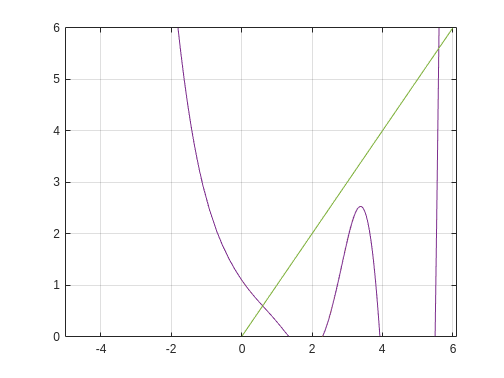

fplot(f(x),[-2 6]);
hold on
grid on
fplot(x)
ylim([0 6])

[p] = fixpt (f, 0.1, 1e-8, 30)

maximum number of iterations exceeded


p =    0.597184915671571
